# Abundance-growth space of a synthetic community of two *E. coli* auxotrophs

## Author(s): Sebastián N. Mendoza, Center for Mathematical Modeling, University of Chile, Chile. MATLAB implementation based on the Python code and tutorials of N.E. Jiménez et al. ([https://github.com/mathomics/ecosystem](https://github.com/mathomics/ecosystem))

## Reviewer(s):

## INTRODUCTION

In this tutorial we reproduce the analysis of a synthetic community of two *Escherichia coli* strains auxotrophic for different amino acids, presented in the supplementary material of Jiménez et al. [1] (notebook `sup_coli_synthetic_com.ipynb`). Zhang and Reed [2] showed that a lysine auxotroph (Δ_lysA_) and a leucine auxotroph (Δ_leuA_) can grow together by cross-feeding the amino acid that the partner cannot synthesize. Here, each strain is represented by a copy of the genome-scale model _i_AF1260 [3] with a knockout:

- `ec_minus_lys`: knockout of diaminopimelate decarboxylase (`DAPDC`), requires lysine.

- `ec_minus_leu`: knockout of 2-isopropylmalate synthase (`IPPS`), requires leucine.

The abundance-growth space of the community is explored by building a grid over the fraction of the lysine auxotroph and the community growth rate, checking the feasibility of each point, computing qualitative flux variability analysis (FVA) on the feasible points and clustering them according to their qualitative flux states (see `tutorial_ecosystemToyExample` for a description of the method).

## MATERIALS - EQUIPMENT SETUP

- MATLAB. No additional MATLAB toolbox is required. Optionally, the Parallel Computing Toolbox speeds up the flux variability analyses (see Step 8).

- The COBRA Toolbox, initialized with `initCobraToolbox`. The functions used in this tutorial are in the folder `src/analysis/ecosystem` and the model _i_AF1260 is distributed with the COBRA Toolbox (`iAF1260.mat`).

- A solver for linear programming problems. A commercial solver (Gurobi or IBM CPLEX) is strongly recommended for the qualitative FVA of Step 8.

global CBTDIR
if isempty(CBTDIR)
    initCobraToolbox(false);
end
% use Gurobi if available, GLPK otherwise
if ~changeCobraSolver('gurobi', 'LP', 0)
    changeCobraSolver('glpk', 'LP');
end
% solver tolerances of 1e-7 (default tolerance of cobrapy, used by the Python implementation)
changeCobraSolverParams('LP', 'optTol', 1e-7);
changeCobraSolverParams('LP', 'feasTol', 1e-7);

## PROCEDURE

## Step 1: Load the *E. coli* model

**TIMING**: ~5 s

model = getDistributedModel('iAF1260.mat');

Each model.subSystems{x} is a character array, and this format is retained.


printRxnFormula(model, 'BIOMASS_Ec_iAF1260_core_59p81M');

BIOMASS_Ec_iAF1260_core_59p81M	0.000223 10fthf_c + 0.000223 2ohph_c + 0.000223 amet_c + 0.004737 ca2_c + 0.2958 arg__L_c + 0.004737 cl_c + 0.2411 asn__L_c + 0.000576 coa_c + 0.2411 asp__L_c + 0.003158 cobalt2_c + 59.984 atp_c + 0.5137 ala__L_c + 0.1335 ctp_c + 0.003158 cu2_c + 0.09158 cys__L_c + 0.02617 dttp_c + 0.02617 datp_c + 0.02702 dctp_c + 0.02702 dgtp_c + 0.000223 fad_c + 0.007106 fe2_c + 0.007106 fe3_c + 54.462 h2o_c + 0.01945 kdo2lipid4_e + 0.2632 gln__L_c + 0.2632 glu__L_c + 0.4505 leu__L_c + 0.09474 his__L_c + 0.6126 gly_c + 0.3432 lys__L_c + 0.2905 ile__L_c + 0.2151 gtp_c + 0.1776 k_c + 0.007895 mg2_c + 0.000223 mlthf_c + 0.1537 met__L_c + 0.003158 mn2_c + 0.003158 mobd_c + 0.1759 phe__L_c + 0.000223 pheme_c + 0.01389 murein5px4p_p + 0.001831 nad_c + 0.000447 nadp_c + 0.02233 pe160_c + 0.04148 pe160_p + 0.011843 nh4_c + 0.02632 pe161_c + 0.04889 pe161_p + 0.2211 pro__L_c + 0.000223 ribflv_c + 0.000223 thf_c + 0.000223 thmpp_c + 0.2537 thr__L_c + 0.000223 pydx5p_c + 0.2158 s

## Step 2: Construction of the auxotrophic strains

**TIMING**: ~10 s

The lysine auxotroph cannot synthesize lysine (`DAPDC` knockout) and is allowed to take up and secrete lysine. We verify the lysine requirement by flux variability analysis of the exchanges of leucine and lysine at 10% of the maximum growth rate.

exports = {'EX_leu__L_e'; 'EX_lys__L_e'};
ecMinusLys = changeRxnBounds(model, 'DAPDC', 0, 'b');
ecMinusLys = changeRxnBounds(ecMinusLys, 'EX_lys__L_e', -1000, 'l');
ecMinusLys = changeRxnBounds(ecMinusLys, 'EX_lys__L_e', 1000, 'u');
solLys = optimizeCbModel(ecMinusLys);
fprintf('ec_minus_lys maximum growth rate: %.4f h-1\n', solLys.f);

ec_minus_lys maximum growth rate: 0.7679 h-1


[minFlux, maxFlux] = fluxVariability(ecMinusLys, 10, 'max', exports);
table(exports, minFlux, maxFlux)

ans = 2x3 table
        exports        minFlux     maxFlux 
    _______________    _______    _________

    {'EX_leu__L_e'}         0        5.4615
    {'EX_lys__L_e'}     -1000     -0.026354


The leucine auxotroph cannot synthesize leucine (`IPPS` knockout):

ecMinusLeu = changeRxnBounds(model, 'IPPS', 0, 'b');
ecMinusLeu = changeRxnBounds(ecMinusLeu, 'EX_leu__L_e', -1000, 'l');
ecMinusLeu = changeRxnBounds(ecMinusLeu, 'EX_leu__L_e', 1000, 'u');
solLeu = optimizeCbModel(ecMinusLeu);
fprintf('ec_minus_leu maximum growth rate: %.4f h-1\n', solLeu.f);

ec_minus_leu maximum growth rate: 0.7763 h-1


[minFlux, maxFlux] = fluxVariability(ecMinusLeu, 10, 'max', exports);
table(exports, minFlux, maxFlux)

ans = 2x3 table
        exports        minFlux      maxFlux 
    _______________    ________    _________

    {'EX_leu__L_e'}    -0.34974    -0.034974
    {'EX_lys__L_e'}           0       5.4923


## Step 3: Build the community model

**TIMING**: ~5 s

The member prefixes are `eco_lys` and `eco_leu`. All the boundary reactions of the members (exchanges and demands) are connected through the pool.

eco = createEcosystemModel({ecMinusLys, ecMinusLeu}, {'eco_lys', 'eco_leu'}, ...
    'communityName', 'eco2', 'communityID', 'eco2');

1. Storing exchanged metabolites information ...
2. Updating member model objects ids ...
3. Storing member objectives ...
4. Merging member models ...
{'eco_lys_BIOMASS_Ec_iAF1260_core_59p81M': 1}
{'eco_leu_BIOMASS_Ec_iAF1260_core_59p81M': 1}
5. Creating pool compartment, metabolites and reactions ...
6. Updating compartment names ...
Done. Community model created
Created community model from 2 member models:
General stats:
model (0):
	 id = iAF1260, prefix = eco_lys
		 reactions = 2382
		 exchange metabolites = 304
model (1):
	 id = iAF1260, prefix = eco_leu
		 reactions = 2382
		 exchange metabolites = 304
community model:
	 id = eco2, name = eco2
		 reactions = 5068
		 exchange metabolites = 304
Exchange metabolite conflicts (formula, charge, name, id) = 0
Community exchange reaction bounds: (-1000, 1000)


eco.objectives

ans = 2x1 cell array
    {'eco_lys_BIOMASS_Ec_iAF1260_core_59p81M'}
    {'eco_leu_BIOMASS_Ec_iAF1260_core_59p81M'}


## Step 4: Set the simulation conditions

**TIMING**: < 1 s

Zhang and Reed [2] reported amino acid uptake rates of the single cultured strains of 0.161 (Δ_lysA_, lysine) and 0.220 (Δ_leuA_, leucine) mmol/gDW/h. In the scenario `sim_glc_cons_AA_prod_no_AA` of [1], the glucose uptake of the community is limited to 10 mmol/gDW/h, with a biological constraint of 10 on the uptake of each member, oxygen uptake is limited to 15 and the medium is not supplemented with leucine or lysine. The secretion of the amino acid required by the partner is limited to 0.2 mmol/gDW/h.

eco = setEcosystemPoolBounds(eco, {'glc__D_e'}, [-10 1000], -10);
eco = setEcosystemPoolBounds(eco, {'lys__L_e'}, [0 1000], -0.161);
eco = setEcosystemPoolBounds(eco, {'leu__L_e'}, [0 1000], -0.22);
eco = setEcosystemPoolBounds(eco, {'o2_e'}, [-15 1000], -15);
eco.model = changeRxnBounds(eco.model, 'eco_leu_EX_lys__L_e', 0.2, 'u');
eco.model = changeRxnBounds(eco.model, 'eco_lys_EX_leu__L_e', 0.2, 'u');

**TIP**: the alternative scenario `sim_glc_cons_AA_prod_001_AA` supplements the medium with 0.01 mmol/gDW/h of leucine and lysine:

`eco = setEcosystemPoolBounds(eco, {'lys__L_e', 'leu__L_e'}, [-0.01 1000], -0.161);`

The maximum community growth (sum of the member growth rates, without abundance constraints) is:

solCom = optimizeCbModel(eco.model);
fprintf('Maximum community growth (sum of member biomasses): %.4f h-1\n', solCom.f);

Maximum community growth (sum of member biomasses): 0.7042 h-1


## Step 5: Select the reactions to analyze

**TIMING**: ~3 min (Gurobi); longer with open-source solvers

Non-blocked reactions of the community model are computed by FVA.

eco = setEcosystemClusterReactions(eco);

Missing FCA results
Using non-blocked reactions only
Total reactions considered for fva and clustering: 3159


## Step 6: Build the abundance-growth grid

**TIMING**: ~1 s

eco = buildEcosystemGrid(eco, 'numPoints', 10, 'ignoreMaintenance', true);

Maximum community: 0.857595


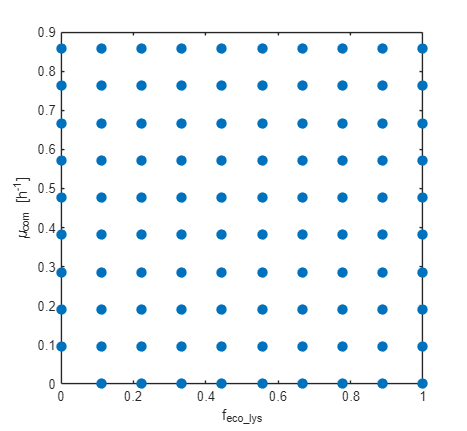

plotEcosystemGrid(eco, 'toPlot', 'none', 'xlabel', 'f_{eco\_lys}');

## Step 7: Feasibility of the grid points

**TIMING**: ~5 s

eco = checkEcosystemGridFeasibility(eco, 'updateBounds', true);

grid feasible points: 23 / 99


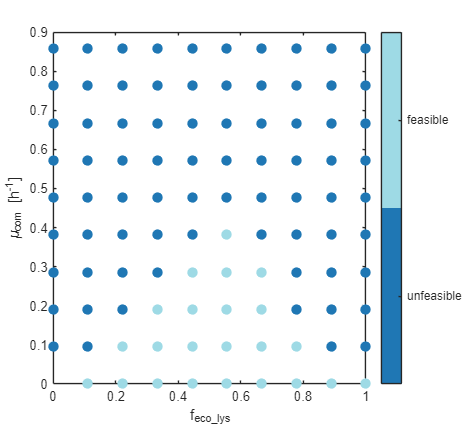

plotEcosystemGrid(eco, 'toPlot', 'feasible', 'xlabel', 'f_{eco\_lys}');

Since each strain depends on the amino acid produced by its partner, the community cannot grow when one of the strains is absent or highly predominant, and the range of feasible compositions narrows as the community growth increases.

## Step 8: Qualitative flux variability analysis

**TIMING**: ~50 min (Gurobi, 3 parallel workers) to several hours (GLPK)

**CRITICAL STEP**: this is the most demanding step, since two LPs are solved for each non-blocked reaction (~3,000) at each feasible point. To speed it up you can open a parallel pool before running the tutorial (`parpool`, Parallel Computing Toolbox), which is used by `fluxVariability`, or restrict the analysis to exchange reactions:

`eco.rxn2cluster = eco.rxn2cluster(contains(eco.rxn2cluster, 'EX_'));`

eco = ecosystemQualitativeFVA(eco, 'updateBounds', true, 'printLevel', 2);

Running qualitative fva over grid feasible points...
point 1/23: [0.1111 0.0000]
point 2/23: [0.2222 0.0000]
point 3/23: [0.3333 0.0000]
point 4/23: [0.4444 0.0000]
point 5/23: [0.5556 0.0000]
point 6/23: [0.6667 0.0000]
point 7/23: [0.7778 0.0000]
point 8/23: [0.8889 0.0000]
point 9/23: [1.0000 0.0000]
point 10/23: [0.2222 0.0953]
point 11/23: [0.3333 0.0953]
point 12/23: [0.4444 0.0953]
point 13/23: [0.5556 0.0953]
point 14/23: [0.6667 0.0953]
point 15/23: [0.7778 0.0953]
point 16/23: [0.3333 0.1906]
point 17/23: [0.4444 0.1906]
point 18/23: [0.5556 0.1906]
point 19/23: [0.6667 0.1906]
point 20/23: [0.4444 0.2859]
point 21/23: [0.5556 0.2859]
point 22/23: [0.6667 0.2859]
point 23/23: [0.5556 0.3812]
Qualitative FVA computed for 23 points and 3159 reactions.


## Step 9: Clustering of the grid points

**TIMING**: < 1 s

eco = clusterEcosystemPoints(eco, 'method', 'hierarchical', 'k', 8);

Calculating jaccard distances between grid points...
Clustering grid points ...
Done!


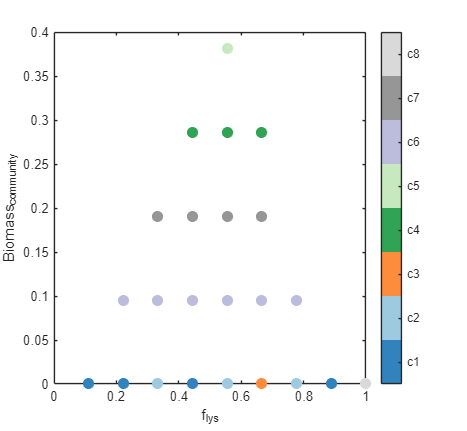

plotEcosystemGrid(eco, 'toPlot', 'cluster', 'colormap', 'tab20c', 'markerSize', 70, ...
    'xlabel', 'f_{lys}', 'ylabel', 'Biomass_{community}');

## Step 10: Reactions that characterize the clusters

**TIMING**: < 1 s

Representative qualitative states of the reactions that change among clusters (threshold of 80% of the points of a cluster):

[repTable, repValues, rxnIds] = getEcosystemClusterReactionValues(eco, 'thr', 0.8, 'changing', true);
fprintf('%d reactions change their representative state among clusters\n', height(repTable));

1852 reactions change their representative state among clusters


head(repTable, 20)

                              c1         c2         c3        c4        c5        c6        c7        c8  
                            _______    _______    ______    ______    ______    ______    ______    ______

    EX_15dap_e              {'0+' }    {'0+' }    {'0+'}    {'0+'}    {'0+'}    {'0+'}    {'0+'}    {'0' }
    EX_4hba_c               {'0'  }    {'0'  }    {'0' }    {'+' }    {'+' }    {'+' }    {'+' }    {'0' }
    EX_ca2_e                {'0'  }    {'0'  }    {'0' }    {'-' }    {'-' }    {'-' }    {'-' }    {'0' }
    EX_cl_e                 {'0'  }    {'0'  }    {'0' }    {'-' }    {'-' }    {'-' }    {'-' }    {'0' }
    EX_cobalt2_e            {'0'  }    {'0'  }    {'0' }    {'-' }    {'-' }    {'-' }    {'-' }    {'0' }
    EX_cu2_e                {'0'  }    {'0'  }    {'0' }    {'-' }    {'-' }    {'-' }    {'-' }    {'0' }
    EX_h2o_e                {'-+' }    {'-+' }    {'-+'}    {'++'}    {'++'}    {'-+'}    {'-+'}    {'-+'}
    EX_hmfurn_c             {'0+' } 

Reactions whose qualitative states change between the cluster of the point with the highest community growth ([0.56, 0.38]) and the cluster of the points with a low community growth ([0.44, 0.10]). These clusters are selected by grid point because cluster labels depend on the clustering of the points with null growth, whose qualitative states are affected by numerical noise (in [1] they were labeled c3 and c4).

analyzedPoints = eco.points(eco.qualPointIndex, :);
[~, iHigh] = min(sum((analyzedPoints - [0.56, 0.38]) .^ 2, 2));
[~, iLow] = min(sum((analyzedPoints - [0.44, 0.10]) .^ 2, 2));
compTable = compareEcosystemClusters(repValues, rxnIds, eco.clusters(iHigh), eco.clusters(iLow))

compTable = 18x2 table
                          c5        c6  
                        ______    ______

    EX_h2o_e            {'++'}    {'-+'}
    EX_o2_e             {'--'}    {'-0'}
    eco_leu_ATPS4rpp    {'++'}    {'-+'}
    eco_leu_EX_h2o_e    {'++'}    {'-+'}
    eco_leu_EX_o2_e     {'--'}    {'-0'}
    eco_leu_H2Otex      {'--'}    {'-+'}
    eco_leu_H2Otpp      {'--'}    {'-+'}
    eco_leu_O2tex       {'++'}    {'0+'}
    eco_leu_O2tpp       {'++'}    {'0+'}
    eco_leu_RPI         {'--'}    {'-+'}
    eco_lys_ATPS4rpp    {'++'}    {'-+'}
    eco_lys_EX_h2o_e    {'++'}    {'-+'}
    eco_lys_EX_o2_e     {'--'}    {'-0'}
    eco_lys_H2Otex      {'--'}    {'-+'}
    eco_lys_H2Otpp      {'--'}    {'-+'}
    eco_lys_O2tex       {'++'}    {'0+'}


## Step 11: Functional relationship between the lysine exchanges

**TIMING**: ~2 min

Quantitative flux coupling analysis between the lysine exchange of the lysine auxotroph (uptake) and that of the leucine auxotroph (secretion), on points with different compositions and community growth rates. Fluxes are normalized by the fraction of each strain (mmol/gDW of strain/h).

gridX = [0.3, 0.5, 0.7];
gridY = [0.2, 0.1];
qfca = quantitativeFluxCoupling(eco, gridX, gridY, {'eco_lys_EX_lys__L_e', 'eco_leu_EX_lys__L_e'});

Quantitative Flux Coupling analysis
 Initializing grid...
the closest point to [0.3, 0.2] is [0.3333, 0.1906], at a distance of 0.03464
the closest point to [0.5, 0.2] is [0.4444, 0.1906], at a distance of 0.05635
the closest point to [0.7, 0.2] is [0.6667, 0.1906], at a distance of 0.03464
the closest point to [0.3, 0.1] is [0.3333, 0.0953], at a distance of 0.03366
the closest point to [0.5, 0.1] is [0.4444, 0.0953], at a distance of 0.05575
the closest point to [0.7, 0.1] is [0.6667, 0.0953], at a distance of 0.03366
Selected point [0.3333 0.1906], fractions [0.3333 0.6667]
Selected point [0.4444 0.1906], fractions [0.4444 0.5556]
Selected point [0.6667 0.1906], fractions [0.6667 0.3333]
Selected point [0.3333 0.0953], fractions [0.3333 0.6667]
Selected point [0.4444 0.0953], fractions [0.4444 0.5556]
Selected point [0.6667 0.0953], fractions [0.6667 0.3333]


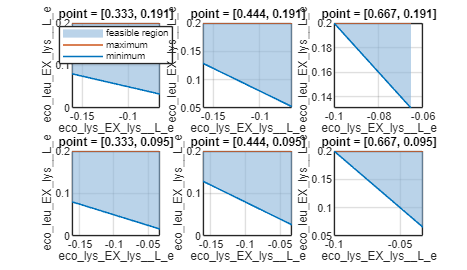

plotQuantitativeFluxCoupling(qfca, 'colWrap', 3);

## TROUBLESHOOTING

- **Problem**: Step 8 takes too long. **Possible reason**: open-source LP solvers are much slower than commercial ones for genome-scale models. **Solution**: use Gurobi or IBM CPLEX (free academic licenses), a parallel pool (`parpool`) or restrict `eco.rxn2cluster` to exchange reactions.

- **Problem**: different number of non-blocked reactions than in [1] (3,159). **Possible reason**: numerical tolerances of the solver. **Solution**: adjust the tolerance of `setEcosystemClusterReactions` (`'tol'`, default 1e-7).

- **Problem**: cluster labels differ from those of the original notebook. **Possible reason**: small numerical differences between LP solvers can change the qualitative states of some points (the clustering itself gives the same labels as SciPy). **Solution**: compare clusters through their representative states rather than their labels.

## TIMING

- Steps 1-4: ~10 s

- Step 5: ~3 min (Gurobi)

- Steps 6-7: ~10 s

- Step 8: ~50 min (Gurobi, 3 parallel workers) to several hours (GLPK)

- Steps 9-10: < 1 s

- Step 11: ~2 min

Times measured with Gurobi 9.5 and a parallel pool of 3 workers (`parpool(3)`) opened before running the tutorial.

## ANTICIPATED RESULTS

The maximum growth rates of the auxotrophs are 0.7679 (`ec_minus_lys`) and 0.7763 h-1 (`ec_minus_leu`) when the amino acid is supplemented. Without supplementation, the lysine auxotroph requires a lysine uptake of at least 0.026 mmol/gDW/h at 10% of its maximum growth, and the leucine auxotroph a leucine uptake between 0.035 and 0.350 mmol/gDW/h. The community model reaches a maximum growth of 0.704 h-1 with the amino acid secretion limits, and of 0.858 h-1 in the relaxed problem used to build the grid (without ATP maintenance). As in the original analysis, 3,159 reactions are non-blocked and 23 of the 99 grid points are feasible: all compositions at null growth and a range of intermediate compositions that narrows as the community growth increases (up to 0.38 h-1, f = 0.56).

With 8 clusters, 1,852 reactions change their representative state among clusters. The 15 feasible points with positive growth are grouped as in the Python implementation, with the same labels: c6 (growth 0.095), c7 (0.19), c4 (0.29), c5 (0.38) and c8 (f = 1, null growth). The 8 points with null growth are grouped in clusters 1 to 3; their grouping depends on fluxes of the order of 1e-9 (see below) and may change between runs.

The comparison of the cluster with the highest growth (c5) and the cluster with low growth (c6) recovers exactly the 18 reactions and states reported in [1] (clusters c3 and c4 of the original notebook): exchanges of oxygen and water of the community and of both strains, oxygen and water transport (`O2tex`, `O2tpp`, `H2Otex`, `H2Otpp`), ATP synthase (`ATPS4rpp`, `++` vs `-+`) and ribose-5-phosphate isomerase (`RPI`, `--` vs `-+`): at the highest community growth both strains must take up oxygen and secrete water, whereas at low growth oxygen uptake is optional and water can be taken up or secreted.

**Comparison with the Python implementation**: running the original Python code (cobrapy 0.26.3, Gurobi 9.5.2) on the same data gives the same 23 feasible points and 3,159 reactions, and 8 non-empty clusters (the notebook of [1] reports 6, which shows that the original results also depend on the computational environment). The clustering methods are equivalent: clustering the Python qualitative vectors with `clusterEcosystemPoints` gives exactly the Python labels, and SciPy gives exactly the MATLAB labels on the MATLAB vectors. With solver tolerances of 1e-7 (as cobrapy), the MATLAB and Python qualitative vectors differ in 12-17 of 72,657 states, all of them fluxes of the order of 1e-9 at points with null growth (numerical noise), which are classified arbitrarily because the threshold `delta` = 1e-9 is below the tolerance of the solvers. With a tolerance of 1e-6, fluxes of biomass precursors of the order of 1e-6 also differ (44 different states).

## REFERENCES

[1] Jiménez, N.E., Acuña, V., Cortés, M.P., Eveillard, D., Maass, A. Unveiling abundance-dependent metabolic phenotypes of microbial communities. *mSystems* **8**, e00492-23 (2023).

[2] Zhang, X., Reed, J.L. Adaptive evolution of synthetic cooperating communities improves growth performance. *PLoS One* **9**, e108297 (2014).

[3] Feist, A.M. et al. A genome-scale metabolic reconstruction for *Escherichia coli* K-12 MG1655 that accounts for 1260 ORFs and thermodynamic information. *Mol. Syst. Biol.* **3**, 121 (2007).